ds = gk_datasetQuery('mouseID', 'M827', 'day','d0','session','ses1','expID','DR');

% this is the result after FISSA correction (this is plane by plane)
plane=2;
xpr = gk_getTunedROIs(ds, 'deltaf_result',2, 3, 0.0001,0.7,false,plane);

This has been calculated before. Loading...


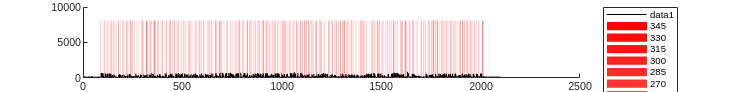

% plot the full time-course of a well tuned neuron
gk_plotStimNeuron(ds, xpr.tunedGlobalIDs(3),plane)

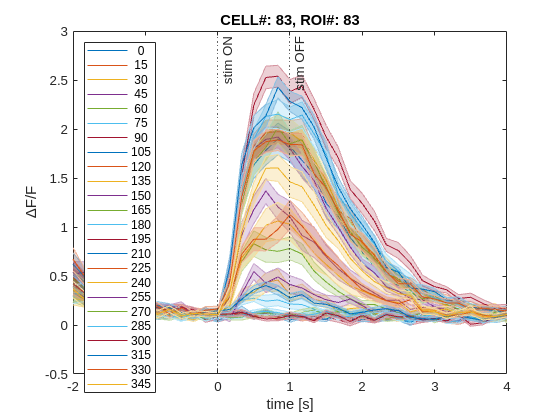

% plot the average responses per condition
figure;
gk_plot_trials(xpr,xpr.onTunedIDs_allGrp(xpr.sortedOnTunedIDs_allGrp(3)),1,xpr.stimValues,'direction [deg]')

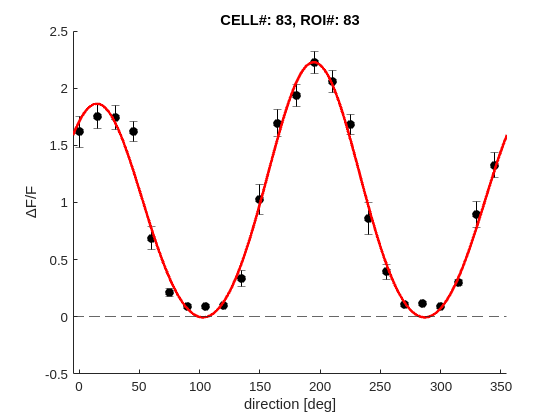

% plot the tuning and model fit
figure;
gk_plot_tuning(xpr,xpr.onTunedIDs_allGrp(xpr.sortedOnTunedIDs_allGrp(3)),1,xpr.stimValues,'direction [deg]')

% this is the result with just correcting with a factor of 0.7*Fneu
xpr = gk_getTunedROIs(ds, 'F',2, 3, 0.0001,0.7,false,'combined');

This has been calculated before. Loading...


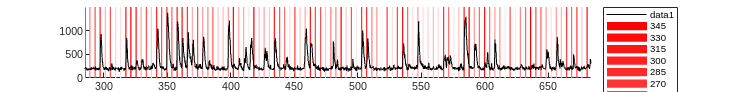

% plot the full time-course of a well tuned neuron
gk_plotStimNeuron(ds, xpr.tunedGlobalIDs(1))

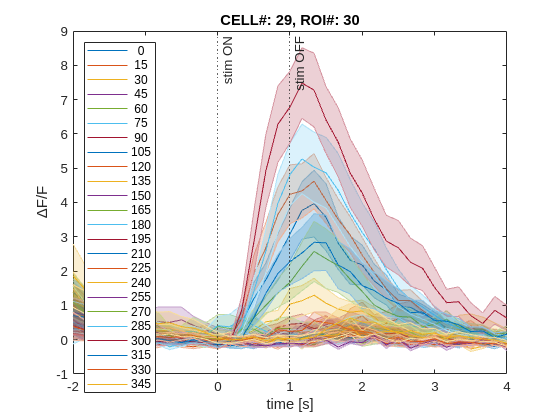

% plot the average responses per condition
figure;
gk_plot_trials(xpr,xpr.onTunedIDs_allGrp(xpr.sortedOnTunedIDs_allGrp(1)),1,xpr.stimValues,'direction [deg]')

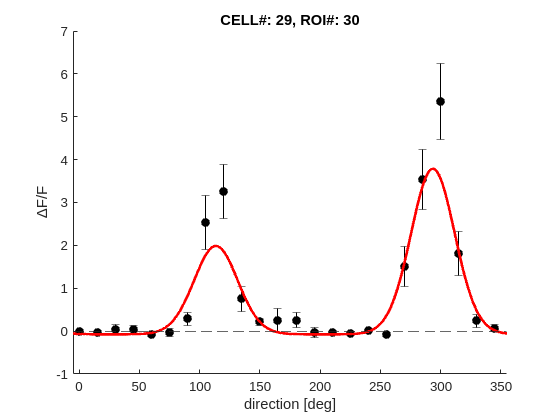

% plot the tuning and model fit
figure;
gk_plot_tuning(xpr,xpr.onTunedIDs_allGrp(xpr.sortedOnTunedIDs_allGrp(1)),1,xpr.stimValues,'direction [deg]')